# IR Examination 

*This script has the intention of studying the IR based on:*

- ***The Power Spectral Density (Using the Welch Method)***

*The average PSD is taken for different Resolutions = 45 ° and 90 °*

- ***Examining the reverberation effect on the IR and the PSD ***

*The amount of reverberation can be controlled by specifying the duration of the steady-state response of the Impulse Response.*

clc; close all; clear;
addpath(genpath(fullfile('../')));

## Step 1: Gather IRs of different reverb

IRLen = 40;
fs = 44100;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth

% IR Set with Duration = 1000ms
nameIR1000ms = 'IR44K_2s_1000ms';
IR1000ms = load(dir+nameIR1000ms).IR44K_2s_1000ms;
IR1000ms =IR1000ms(:,2);
IR1000ms = [IR1000ms{:}];

% IR Set with Duration = 500ms
nameIR500ms = 'IR44K_2s_500ms';
IR500ms = load(dir+nameIR500ms).IR44K_2s_500ms;
IR500ms =IR500ms(:,2);
IR500ms = [IR500ms{:}];

% IR Set with Duration = 100ms
nameIR100ms = 'IR44K_2s_100ms';
IR100ms = load(dir+nameIR100ms).IR44K_2s_100ms;
IR100ms =IR100ms(:,2);
IR100ms = [IR100ms{:}];

% IR Set with Duration = 50ms
nameIR50ms = 'IR44K_2s_50ms';
IR50ms = load(dir+nameIR50ms).IR44K_2s_50ms;
IR50ms =IR50ms(:,2);
IR50ms = [IR50ms{:}];

% IR Set with Duration = 10ms
nameIR10ms = 'IR44K_2s_10ms';
IR10ms = load(dir+nameIR10ms).IR44K_2s_10ms;
IR10ms =IR10ms(:,2);
IR10ms = [IR10ms{:}];

## The entire set of impulse responses

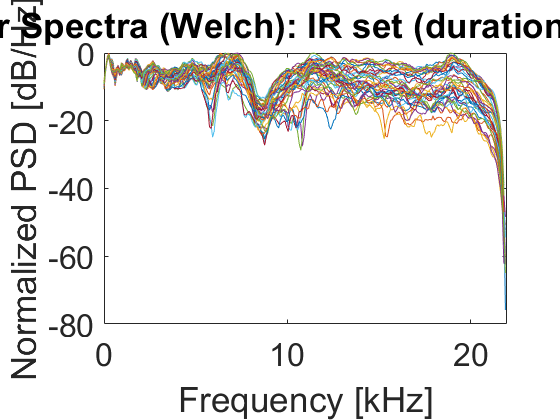

% Calculate PSD using Welch method:
segmentLength = 512;        % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
noverlap = segmentLength/2; % 50 percent overlap
win = hamming(512);            % 512 sample-length hanning window
Impulse_10ms_psd = zeros((segmentLength/2)+1,IRLen);
figure;

df = fs/(2*((segmentLength/2)+1));
f = 0:df:(fs-df)/2;

for i = 1:IRLen
    ir = IR10ms(:,i);
    % Use Welch's method with fft input (return 'one-sided' psd)
    ir_windowed_fft  = welch_window(ir,segmentLength,noverlap, win);    % Perform windowing with 50% overlap and apply fft
    Impulse_10ms_psd(:,i) = welch_input_fft(ir_windowed_fft, win, fs);       % Calculate periodograms and average
    Impulse_10ms_psd(:,i) = normalize(Impulse_10ms_psd(:,i),'range');
    plot(f/1000,10*log10(Impulse_10ms_psd(:,i))); hold on;
end;
xlabel("Frequency [kHz]"); ylabel("Normalized PSD [dB/Hz]"); title("Power Spectra (Welch): IR set (duration = 10ms)", "FontSize",48);
ax = gca;
ax.FontSize = 24;

# Examining The Averaging method

*We want to see if weighted averaging offers a better spectral shape (holding the featured peaks and notches).*

*The traditional average (mean) and the weighted average are visually compared.*

## Step 2(a): Take the Average Welch PSD for the IR set with 20 ms duration

% Calculate PSD using Welch method:
segmentLength = 512;        % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
noverlap = segmentLength/2; % 50 percent overlap
win = hamming(512);            % 512 sample-length hanning window
Impulse_10ms_psd = zeros((segmentLength/2)+1,IRLen);

for i = 1:IRLen
    ir = IR10ms(:,i);
    % Use Welch's method with fft input (return 'one-sided' psd)
    ir_windowed_fft  = welch_window(ir,segmentLength,noverlap, win);    % Perform windowing with 50% overlap and apply fft
    Impulse_10ms_psd(:,i) = welch_input_fft(ir_windowed_fft, win, fs);       % Calculate periodograms and average
    

end
Impulse_10ms_psd = normalize(Impulse_10ms_psd,'range');

% Average the IR to directions: [0, 90, 180, 270]

vec_90 = [1:6, 36:40; 6:16; 16:26; 26:36];
vec_45 = [1:3, 39,40; 4:8; 9:13; 14:18; 19:23; 24:28; 29:33; 34:38];
average_10ms_psd_90 = zeros((segmentLength/2)+1,4);       % Average Power Spectral Density for IRs with resolution = 90 °
average_10ms_psd_45 = zeros((segmentLength/2)+1,8);       % Average Power Spectral Density for IRs with resolution = 45 °

for i = 1:4
    % Save the averaged PSD for 90 degree Resolution:
    psd_set = Impulse_10ms_psd(:,vec_90(i,:));
    average_10ms_psd_90(:,i) = sum(psd_set,2)/10;
end

for i = 1:8
    % Save the averaged PSD for 45 degree Resolution:
    psd_set = Impulse_10ms_psd(:,vec_45(i,:));
    average_10ms_psd_45(:,i) = sum(psd_set,2)/5;
end

### Extra: Visualize the averaging for 0 degrees 

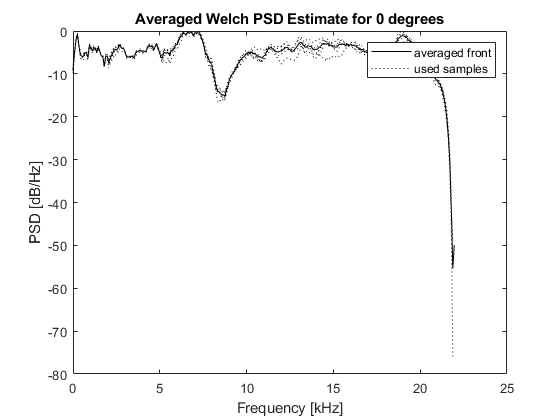

df = fs/(2*((segmentLength/2)+1));
f = 0:df:(fs-df)/2;

color = ['r', 'b', 'g', 'm', 'k'];
line = ["-", "-", "--", "-.", ":"];
% Plot the averaged Power Spectral Density
plot(f/1000, 10*log10(average_10ms_psd_45(:,1)), 'k-'); hold on;
j = 1;
for i = vec_45(1,:)
    plot(f/1000, 10*log10(Impulse_10ms_psd(:,i)), 'Color', 'k', 'LineStyle', ':'); hold on;
    j = j +1;
end
xlabel('Frequency [kHz]');
ylabel('PSD [dB/Hz]');
title('Averaged Welch PSD Estimate for 0 degrees');
labels = categorical(["averaged front","used samples"]);
legend(labels); 
hold off;

### Step 2(b): Try a weighted average for the Welch PSD estimate (IR duration = 20ms)

% Calculate PSD using Welch method:
segmentLength = 512;        % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
noverlap = segmentLength/2; % 50 percent overlap
win = hamming(512);            % 512 sample-length hanning window
Impulse_10ms_psd = zeros((segmentLength/2)+1,IRLen);

for i = 1:IRLen
    ir = IR10ms(:,i);
    % Use Welch's method with fft input (return 'one-sided' psd)
    ir_windowed_fft  = welch_window(ir,segmentLength,noverlap, win);    % Perform windowing with 50% overlap and apply fft
    Impulse_10ms_psd(:,i) = welch_input_fft(ir_windowed_fft, win, fs);       % Calculate periodograms and average
    

end

% Average the IR to directions: [0, 90, 180, 270]

vec_90 = [1:6, 36:40; 6:16; 16:26; 26:36];
weights_90 = [1, 0.8, 0.4, 0.2, 0.1,0.05, 0.05 0.1, 0.2, 0.4, 0.8; ...
    0.05, 0.1, 0.2, 0.4, 0.8, 1, 0.8, 0.4, 0.2, 0.1, 0.05];
vec_45 = [1:3, 39,40; 4:8; 9:13; 14:18; 19:23; 24:28; 29:33; 34:38];
weights_45 = [1, 0.8, 0.4, 0.4, 0.8; ...
    0.4, 0.8, 1, 0.8, 0.4];
Waverage_20ms_psd_90 = zeros((segmentLength/2)+1,4);       % Average Power Spectral Density for IRs with resolution = 90 °
Waverage_20ms_psd_45 = zeros((segmentLength/2)+1,8);       % Average Power Spectral Density for IRs with resolution = 45 °

for i = 1:4
    if i == 1
        weights = weights_90(1,:);
    else
        weights = weights_90(2,:);
    end
    % Save the averaged PSD for 90 degree Resolution:
    psd_set = Impulse_10ms_psd(:,vec_90(i,:));
    psd_set = psd_set .* weights;
    Waverage_20ms_psd_90(:,i) = sum(psd_set,2)/10;
end

for i = 1:8
    if i == 1
        weights = weights_45(1,:);
    else
        weights = weights_45(2,:);
    end
     % Save the averaged PSD for 45 degree Resolution:
    psd_set = Impulse_10ms_psd(:,vec_45(i,:));
    psd_set = psd_set .* weights;       
    Waverage_20ms_psd_45(:,i) = sum(psd_set,2)/5;   
end

### Extra: Visualize the weighted averaging for 0 degrees

df = fs/(2*((segmentLength/2)+1));
f = 0:df:(fs-df)/2;

color = ['r', 'b', 'g', 'm', 'k'];
line = ["-.",":"];
% Plot the averaged Power Spectral Density
plot(f/1000, 10*log10(average_10ms_psd_45(:,1)), 'k-'); hold on;
j = 1;
for i = vec_45(1,:)
    if i == 1
        l = line(1);
    else
        l = line(2);
    end
    plot(f/1000, 10*log10(Impulse_10ms_psd(:,i)), 'Color', 'k', 'LineStyle', l); hold on;
    j = j +1;
end
xlabel('Frequency [kHz]');
ylabel('PSD [dB/Hz]');
title('Weighted Averaged Welch PSD Estimate for 0 degrees');
labels = categorical(["averaged front","weighted 1 sample","other used samples"]);
legend(labels); 
hold off;

## Conclusion on Averaging

**Weighted averaging **

*This method seems to keep the spectral shape of the main direction (0 degrees) intact. However due to the weights the overall PSD lays around 2-3 dB lower.*

** Traditional averaging**

*Standard averaging does not seem to disturb the original spectral shape. We can work with this simple averaging technique in the future.*

## A closer look at the lower frequencies of the PSD

*we examine the lower frequencies by using a logarithmic scale on the frequency axis.*

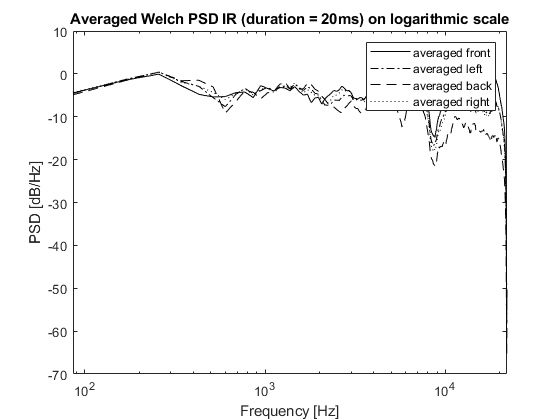

df = fs/(2*((segmentLength/2)+1));
f = 0:df:(fs-df)/2;

color = ['r', 'b', 'g', 'm', 'k'];
line = ["-","-.","--",":"];
% Plot the averaged Power Spectral Density
for i = 1:4
    semilogx(f, 10*log10(average_10ms_psd_90(:,i)),'Color','k', 'LineStyle', line(i)); hold on;
end
j = 1;
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]');
title('Averaged Welch PSD IR (duration = 20ms) on logarithmic scale');
labels = categorical(["averaged front","averaged left","averaged back", "averaged right"]);
legend(labels); 
hold off;

# Examining Reverberation

*We want to have an idea of what the reverberation does to the Power Spectral Density shape.*

*This will give us an idea of what the Classification Model would have to deal with in a real-time environment.*

## Visualizing Reverberation (time-domain)

The reverberation time is approx. the steady-state duration of the IR.

Thus if an Impulse Response lasts 500ms and the Transient Response takes about 5ms, the reverberation is found in the last 495 ms. 

*Note: All IRs start 10ms before the initial Impulse, the duration is however defined as the time after this impulse. *

**The following section visualizes the reverberation for the 500ms and 200 Impulse Response for the direction of 0 degrees:**

t_500ms = 0:1/fs:(length(IR500ms)-1)/fs;
plot(t_500ms,IR500ms(:,1)); xlabel("time [s]"); ylabel("Amplitude"); title("Impulse Response duration = 500ms");

*We see a long reverberation time after the initial Impulse which seems to die out at around 220ms. After that the recording might show static noise (microphone). *

**How does this look for a 20ms duration?**

t_20ms = 0:1/fs:(length(IR10ms)-1)/fs;
plot(t_20ms,IR10ms(:,1)); xlabel("time [s]"); ylabel("Amplitude"); title("Impulse Response duration = 20ms");

*The 20ms duration refers to the time after the initial impulse. We now have less reverberation in the signal. *

***But how does this affect the frequency domain?***

## Gather the Welch PSDs (only for the front (0°) )for a resolution of 90 degrees 

*We expect that reverberation in the time domain adds (unwanted) noise in the frequency domain*

% Calculate PSD using Welch method:
segmentLength = 512;        % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
noverlap = segmentLength/2; % 50 percent overlap
win = hamming(512);         % 512 sample-length hanning window

% Frequency vector for visualization:
df = fs/(2*((segmentLength/2)+1));  % Frequency resolution
f = 0:df:(fs-df)/2;


#### **Average for 500ms duration:**

Impulse_500ms_psd = zeros((segmentLength/2)+1,IRLen);
% Average PSD for 500ms:
for i = 1:IRLen
    ir = IR500ms(:,i);
    % Use Welch's method with fft input (return 'one-sided' psd)
    ir_windowed_fft  = welch_window(ir,segmentLength,noverlap, win);        % Perform windowing with 50% overlap and apply fft
    Impulse_500ms_psd(:,i) = welch_input_fft(ir_windowed_fft, win, fs);     % Calculate periodograms and average 

end
% Average the IR to directions: [0, 90, 180, 270]
vec_90 = [1:6, 36:40; 6:16; 16:26; 26:36];
average_500ms_psd_90 = zeros((segmentLength/2)+1,4);       % Average Power Spectral Density for IRs with resolution = 90 °
for i = 1:4
    % Save the averaged PSD for 90 degree Resolution:
    psd_set = Impulse_500ms_psd(:,vec_90(i,:));
    average_500ms_psd_90(:,i) = sum(psd_set,2)/10;
end


#### **Visualize averaged Power Spectral Density for a duration of 500ms:**

% Plot the averaged Power Spectral Density
line = ["-", "--", "-.", ":"];
for i = 1:4
    semilogx(f/1000, 10*log10(average_500ms_psd_90(:,i)), "Color", 'k', "LineStyle",line(i)); hold on;
end
xlabel('Frequency [kHz]');
ylabel('PSD [dB/Hz]');
title('Averaged Welch PSD Estimate (duration IR = 500ms)');
labels = categorical(["averaged front","Averaged Left", "Averaged Back", "Averaged Right"]);
legend(labels); 
hold off;

#### **Average for 200ms duration:**

Impulse_200ms_psd = zeros((segmentLength/2)+1,IRLen);
% Average PSD for 200ms:
for i = 1:IRLen
    ir = IR100ms(:,i);
    % Use Welch's method with fft input (return 'one-sided' psd)
    ir_windowed_fft  = welch_window(ir,segmentLength,noverlap, win);        % Perform windowing with 50% overlap and apply fft
    Impulse_200ms_psd(:,i) = welch_input_fft(ir_windowed_fft, win, fs);     % Calculate periodograms and average 

end
% Average the IR to directions: [0, 90, 180, 270]
vec_90 = [1:6, 36:40; 6:16; 16:26; 26:36];
average_200ms_psd_90 = zeros((segmentLength/2)+1,4);       % Average Power Spectral Density for IRs with resolution = 90 °
for i = 1:4
    % Save the averaged PSD for 90 degree Resolution:
    psd_set = Impulse_200ms_psd(:,vec_90(i,:));
    average_200ms_psd_90(:,i) = sum(psd_set,2)/10;
end


#### **Visualize averaged Power Spectral Density for a duration of 200ms:**

% Plot the averaged Power Spectral Density
line = ["-", "--", "-.", ":"];
for i = 1:4
    semilogx(f/1000, 10*log10(average_200ms_psd_90(:,i)), "Color", 'k', "LineStyle",line(i)); hold on;
end
xlabel('Frequency [kHz]');
ylabel('PSD [dB/Hz]');
title('Averaged Welch PSD Estimate (duration IR = 200ms)');
labels = categorical(["averaged front","Averaged Left", "Averaged Back", "Averaged Right"]);
legend(labels); 
hold off;

#### **Average for 20ms duration:**

Impulse_10ms_psd = zeros((segmentLength/2)+1,IRLen);
% Average PSD for 20ms:
for i = 1:IRLen
    ir = IR10ms(:,i);
    % Use Welch's method with fft input (return 'one-sided' psd)
    ir_windowed_fft  = welch_window(ir,segmentLength,noverlap, win);        % Perform windowing with 50% overlap and apply fft
    Impulse_10ms_psd(:,i) = welch_input_fft(ir_windowed_fft, win, fs);     % Calculate periodograms and average 

end
% Average the IR to directions: [0, 90, 180, 270]
vec_90 = [1:6, 36:40; 6:16; 16:26; 26:36];
average_10ms_psd_90 = zeros((segmentLength/2)+1,4);       % Average Power Spectral Density for IRs with resolution = 90 °
for i = 1:4
    % Save the averaged PSD for 90 degree Resolution:
    psd_set = Impulse_10ms_psd(:,vec_90(i,:));
    average_10ms_psd_90(:,i) = sum(psd_set,2)/10;
end


#### **Visualize averaged Power Spectral Density for a duration of 20ms:**

% Plot the averaged Power Spectral Density
line = ["-", "--", "-.", ":"];
for i = 1:4
    semilogx(f/1000, 10*log10(average_10ms_psd_90(:,i)), "Color", 'k', "LineStyle",line(i)); hold on;
end
xlabel('Frequency [kHz]');
ylabel('PSD [dB/Hz]');
title('Averaged Welch PSD Estimate (duration IR = 20ms)');
labels = categorical(["averaged front","Averaged Left", "Averaged Back", "Averaged Right"]);
legend(labels); 
hold off;

## Conclusion

*What we see is that Reverberation seems to flatten the Power Spectral Density. This can be explained by looking at the revererberation as noise which causes the specific peaks and notches in the spectrum to flatten out.*

*Specifically the notch at 5.67 kHz gets flattened out for the Averaged Back, however for the different directions, features seem to dissappear.*

*We zoom in on the energy distribution of the reverberation (i.e. after the initial impulse) to see what happens:*

**The following visualisation is done for duration = 500ms  and the direction of 0 degrees (In the front of the microphone):**

*A specific function: onset_estimation.m is written to determine the time sample at which the Impulse is found. We cut-off 10ms after this initial impulse to ensure that only reverberation is found. (Normally we would use the reverberation time of the room at which we measured the Room Impulse Responses, but due to the recent situation (Covid-19) we were unable to perform this measurement.*

nfft = 512;
reverberation_500ms = cell(40,1);

for i = 1:IRLen
    onset_frame = onset_estimation(IR500ms(:,i), nfft, fs);
    jump = onset_frame + ceil(fs/50); %Add 20 ms after the onset frame 
    reverberation_500ms(i) = {IR500ms(jump:end, i)};
end


Check if signal only contains reverb

t_500ms = 0:1/fs:(length(reverberation_500ms{1})-1)/fs;
plot(t_500ms,reverberation_500ms{1}); xlabel("time [s]"); ylabel("Amplitude"); title("Impulse Response duration = 500ms");

*The precedence effect (first sound incident) seems to be gone. We can now check the PSD and see what is still in the signal*

## Averaging of the cut off IR (500ms) to only reverb (precedence effect is gone)

cut_500ms_psd = zeros((segmentLength/2)+1,IRLen);
% Average PSD for 500ms:
for i = 1:IRLen
    ir = reverberation_500ms{i};
    % Use Welch's method with fft input (return 'one-sided' psd)
    ir_windowed_fft  = welch_window(ir,segmentLength,noverlap, win);        % Perform windowing with 50% overlap and apply fft
    cut_500ms_psd(:,i) = welch_input_fft(ir_windowed_fft, win, fs);     % Calculate periodograms and average 

end
% Average the IR to directions: [0, 90, 180, 270]
vec_90 = [1:6, 36:40; 6:16; 16:26; 26:36];
average_reverb_500ms_psd_90 = zeros((segmentLength/2)+1,4);       % Average Power Spectral Density for IRs with resolution = 90 °
for i = 1:4
    % Save the averaged PSD for 90 degree Resolution:
    psd_set = cut_500ms_psd(:,vec_90(i,:));
    average_reverb_500ms_psd_90(:,i) = sum(psd_set,2)/10;
end


#### **Visualize averaged Power Spectral Density for a duration of 500ms:**

% Plot the averaged Power Spectral Density
line = ["-", "--", "-.", ":"];
for i = 1:4
    plot(f/1000, 10*log10(average_reverb_500ms_psd_90(:,i)), "Color", 'k', "LineStyle",line(i)); hold on;
end
xlabel('Frequency [kHz]');
ylabel('PSD [dB/Hz]');
title('Averaged Welch PSD Estimate (duration IR = 500ms)');
labels = categorical(["averaged front","Averaged Left", "Averaged Back", "Averaged Right"]);
legend(labels); 
hold off;

#### **Analyse the frequency-time domain: Spectrogram (only for the front direction)**

x = IR500ms(:,1);
% Original Speech sample STFT domain: Weighted Overlap Add method
%%%%%%% WOLA parameters %%%%%%%
L = length(x);
N_fft = 512;                        % 512 points
R_fft = N_fft/2;                    % shifting (50% overlap)
win = sqrt(hann(N_fft,'periodic')); % analysis window
N_half = floor(N_fft/2)+1;          % number of bins in onsided FFT 
freqs = 0:fs/N_fft:fs/2;            % one-sided set of actual frequencies

X = calc_STFT(x, fs, win, N_fft, N_fft/R_fft, 'onesided');
[N_freqs, N_frames] = size(X); 
times = [0:(N_half-1)/fs:(L-1)/fs];
times = times(2:end-1);

freqs = [fs/(N_freqs*2):fs/(N_freqs*2):fs/2];

magnitude = abs(X);
phase = rad2deg(angle(X));
phase_max = max(phase, [], 'all');
phase_min = min(phase, [], 'all');
titl = "Spectrogram 500ms IR"; 
imagesc(times,freqs/1000,mag2db(magnitude), [-40, 20]); axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (kHz)'), ...
    title(titl); 
c = gray;
c = flipud(c);
colormap(c);

It seems that we have a lot of low-frequency noise (static noise). Investigate the original signal to see how far the reverb goes. 

However the reverberation does not seem to be entirely gone. We look into the original sine with 2s silence. This will give us a better insight on the reverberation caught in the entire recording.

## An

## Analysis of original IR

nameIR_og = 'IR44K_2s_og';
IR_og = load(dir+nameIR_og).IR44K_2s_og;

x = IR_og{31,2};

% Get Initial impulse of original IR
onset_sample = onset_estimation(x, nfft, fs);
index_1 = onset_sample - (fs/10);
x = x(index_1:index_1+(2*fs));

t = 0:1/fs:(length(x)-1)/fs;
figure;
plot(t,x); xlabel("time [s]"); ylabel("amplitude"); title("time-domain: original signal");

% Original Speech sample STFT domain: Weighted Overlap Add method
%%%%%%% WOLA parameters %%%%%%%
L = length(x);
N_fft = 512;                        % 512 points
R_fft = N_fft/2;                    % shifting (50% overlap)
win = sqrt(hann(N_fft,'periodic')); % analysis window
N_half = floor(N_fft/2)+1;          % number of bins in onsided FFT 
freqs = 0:fs/N_fft:fs/2;            % one-sided set of actual frequencies

X = calc_STFT(x, fs, win, N_fft, N_fft/R_fft, 'onesided');
[N_freqs, N_frames] = size(X); 
times = [0:(N_half-1)/fs:(L-1)/fs];
times = times(2:end-1);

freqs = [fs/(N_freqs*2):fs/(N_freqs*2):fs/2];

magnitude = abs(X);
phase = rad2deg(angle(X));
phase_max = max(phase, [], 'all');
phase_min = min(phase, [], 'all');
titl = "Spectrogram original IR"; 
figure;
imagesc(times,freqs/1000,mag2db(magnitude), [-40, 20]); axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (kHz)'), ...
    title(titl); 
c = gray;
c = flipud(c);
colormap(c);

**High frequencies get absorbed better by materials thus the energy of reflections fades more easily. However low frequencies tend to stay much longer in the room. This reverberation will**

## Averaging of the IR (original) 

ir_og_psd = zeros((segmentLength/2)+1,IRLen);
% Average PSD for og:
for i = 1:IRLen
    ir = IR_og{i,2};
    % Use Welch's method with fft input (return 'one-sided' psd)
    ir_windowed_fft  = welch_window(ir,segmentLength,noverlap, win);        % Perform windowing with 50% overlap and apply fft
    ir_og_psd(:,i) = welch_input_fft(ir_windowed_fft, win, fs);     % Calculate periodograms and average 

end
% Average the IR to directions: [0, 90, 180, 270]
vec_90 = [1:6, 36:40; 6:16; 16:26; 26:36];
average_reverb_og_psd_90 = zeros((segmentLength/2)+1,4);       % Average Power Spectral Density for IRs with resolution = 90 °
for i = 1:4
    % Save the averaged PSD for 90 degree Resolution:
    psd_set = ir_og_psd(:,vec_90(i,:));
    average_reverb_og_psd_90(:,i) = sum(psd_set,2)/10;
end


#### **Visualize averaged Power Spectral Density for og:**

% Plot the averaged Power Spectral Density
line = ["-", "--", "-.", ":"];
for i = 1:4
    plot(f/1000, 10*log10(average_reverb_og_psd_90(:,i)), "Color", 'k', "LineStyle",line(i)); hold on;
end
xlabel('Frequency [kHz]');
ylabel('PSD [dB/Hz]');
title('Averaged Welch PSD Estimate (duration IR = og)');
labels = categorical(["averaged front","Averaged Left", "Averaged Back", "Averaged Right"]);
legend(labels); 